# 6.3 设计Butterworth滤波器和Chebyshev滤波器

## 6.3（1）利用双线性z变换法设计Butterworth数字高通滤波器：  

clear all;
close all;
fp=400;
fs=300;
Fs=1000;
Rp=3;  Rs=35;

wp=2*pi*fp/Fs;
ws=2*pi*fs/Fs;

OmegaP=2*Fs*tan(wp/2);
OmegaS=2*Fs*tan(ws/2);

[N,Wn]=buttord(OmegaP,OmegaS,Rp,Rs,'s');  %选择模拟巴特沃斯低通滤波器的最小阶数 
[z,p,k]=buttap(N);          %创建巴特沃斯模拟低通滤波器 
[Bp,Ap]=zp2tf(z,p,k)        %由零点、极点、增益确定传输函数的分子与分母的系数 

Bp =      0     0     0     0     0     0     1


Ap =     1.0000    3.8637    7.4641    9.1416    7.4641    3.8637    1.0000


[b,a]=lp2hp(Bp,Ap,Wn)       %模拟低通滤波器到模拟高通滤波器的转换 

b = 	1.0e+06 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0031    4.1297


a = 	1.0e+22 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    2.4465



[bz,az]=bilinear(b,a,Fs)   

bz =     0.0006   -0.0038    0.0096   -0.0128    0.0096   -0.0038    0.0006


az =     1.0000    3.2634    4.8207    3.9984    1.9417    0.5193    0.0594


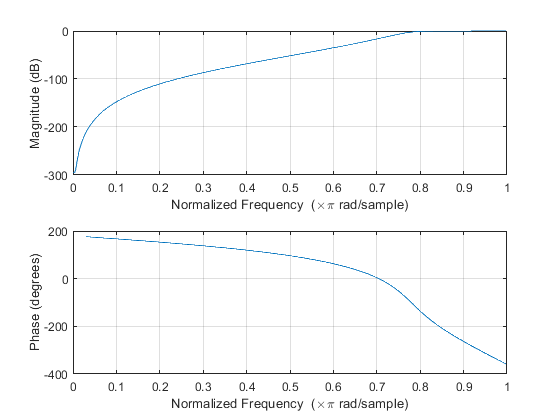

figure(1); 
freqz(bz,az);

## 6.3（2）利用双线性z变换法设计Chebychev数字带通滤波器：  

%----------------------------------------------------------------------------
% exa060603.m, for example 6.6.3;
% To design IIR Butteworth bandstop DF by analog-lowpass,
% ---------------------------------------------------------------------------
clear all;

fp=[300 400];fs=[200 500];
%wp=[.19*pi 0.21*pi];ws=[.198*pi 0.202*pi];
Fs=2000;
rp=3;rs=40;
wp=fp*2*pi/Fs;ws=fs*2*pi/Fs;
%
% Firstly to finish frequency prewarping;
wap=2*Fs*tan(wp./2)

wap = 	1.0e+03 *

    2.0381    2.9062


was=2*Fs*tan(ws./2);
[n,wn]=cheb1ord(wap,was,rp,rs,'s');
% Note: 's'!
[z,p,k]=cheb1ap(n,rp);
[b,a]=zp2tf(z,p,k)

b =          0         0         0         0    0.1253


a =     1.0000    0.5816    1.1691    0.4048    0.1770


bw=wap(2)-wap(1)

bw = 868.0683

w0=sqrt(wap(1)*wap(2))

w0 = 2.4337e+03

[bt,at]=lp2bp(b,a,w0,bw)

bt = 	1.0e+10 *

    7.1147   -0.0000   -0.0000         0         0


at = 	1.0e+27 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    1.2308


%
% Note: z=(2/ts)(z-1)/(z+1);
[bz1,az1]=bilinear(bt,at,Fs)

bz1 = 	1.0e+-3 *

    0.0702   -0.0000   -0.2808   -0.0000    0.4212   -0.0000   -0.2808   -0.0000    0.0702


az1 =     1.0000   -3.5495    8.4668  -12.8267   14.9115  -12.2548    7.7286   -3.0945    0.8331


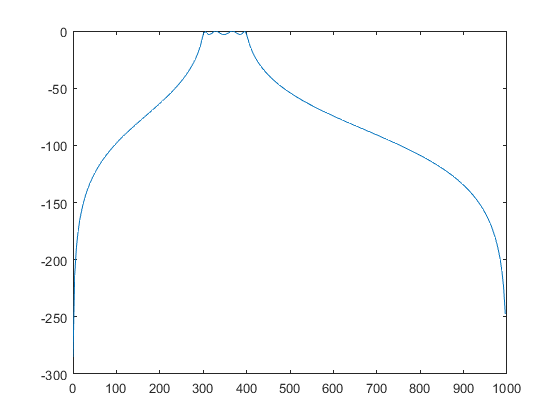

[h,w]=freqz(bz1,az1,256,Fs);
figure(1)
plot(w,20*log10(abs(h)))